clc;
clear;
close all;

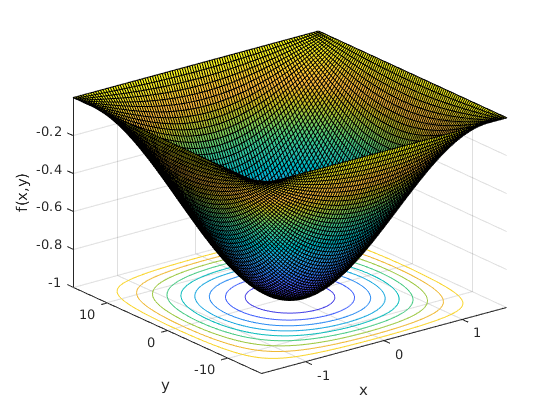

% define the function to minimize
f = @(x,y) -cos(x).*cos(y/10);

% define the domain
x = linspace(-pi/2,pi/2,100);
y = linspace(-10*pi/2,10*pi/2,100);
[xx,yy] = meshgrid(x,y);

% plot the function
figure;
surfc(xx,yy,f(xx,yy));
xlabel('x'); ylabel('y'); zlabel('f(x,y)');

% define search direction for steepest descent (from 1C)
pk_sd = @(x,y) [-sin(x).*cos(y/10); -0.1*cos(x).*sin(y/10)];

% define search direction for newton method (from 1C)
pk_nm = @(x,y) [(-0.5*sin(2*x).*(cos(y/10).^2 + 0.1*sin(y/10).^2))./(cos(x-y/10).*cos(x+y/10));...
                (-0.5*sin(y/5).*(0.1*sin(x).^2 + 100*cos(x).^2))./(cos(x-y/10).*cos(x+y/10))];

% choose values for initial x and y
x0 = -pi/4;
y0 = pi/2;

% run line search algorithms
% set initial vectors
v_sd_ne = [x0;y0];
v_sd_e = [x0;y0];
v_nm_ne = [x0;y0];
v_nm_e = [x0;y0];
% set alpha values for no line search
a_sd_ne = 1;
a_nm_ne = 0.1;

% descent loop
for n=1:1000
    % steepest descent with no line search
    v_sd_ne = v_sd_ne + a_sd_ne*pk_sd(v_sd_ne(1),v_sd_ne(2));
    
    % steepest descent with exact line search
    x = v_sd_e(1); y = v_sd_e(2);
    psd = pk_sd(x,y);
    fes = @(a) f(x+a*psd(1),y+a*psd(2));
    a_sd_e = fminbnd(fes,1e-10,1);
    v_sd_e = v_sd_e + a_sd_e*psd;
    
    % newton method with no line search
    v_nm_ne = v_nm_ne + a_nm_ne*pk_nm(v_nm_ne(1),v_nm_ne(2));
    
    % newton method with exact line search
    x = v_nm_e(1); y = v_nm_e(2);
    pnm = pk_nm(x,y);
    fes = @(a) f(x+a*pnm(1),y+a*pnm(2));
    a_nm_e = fminbnd(fes,1e-10,1);
    v_nm_e = v_nm_e + a_nm_e*pnm;
end